format long;

# Practice Task 3

## A. Fourier series of square wave

Consider the periodic function shown in the figure, which corresponds to a "square wave" 

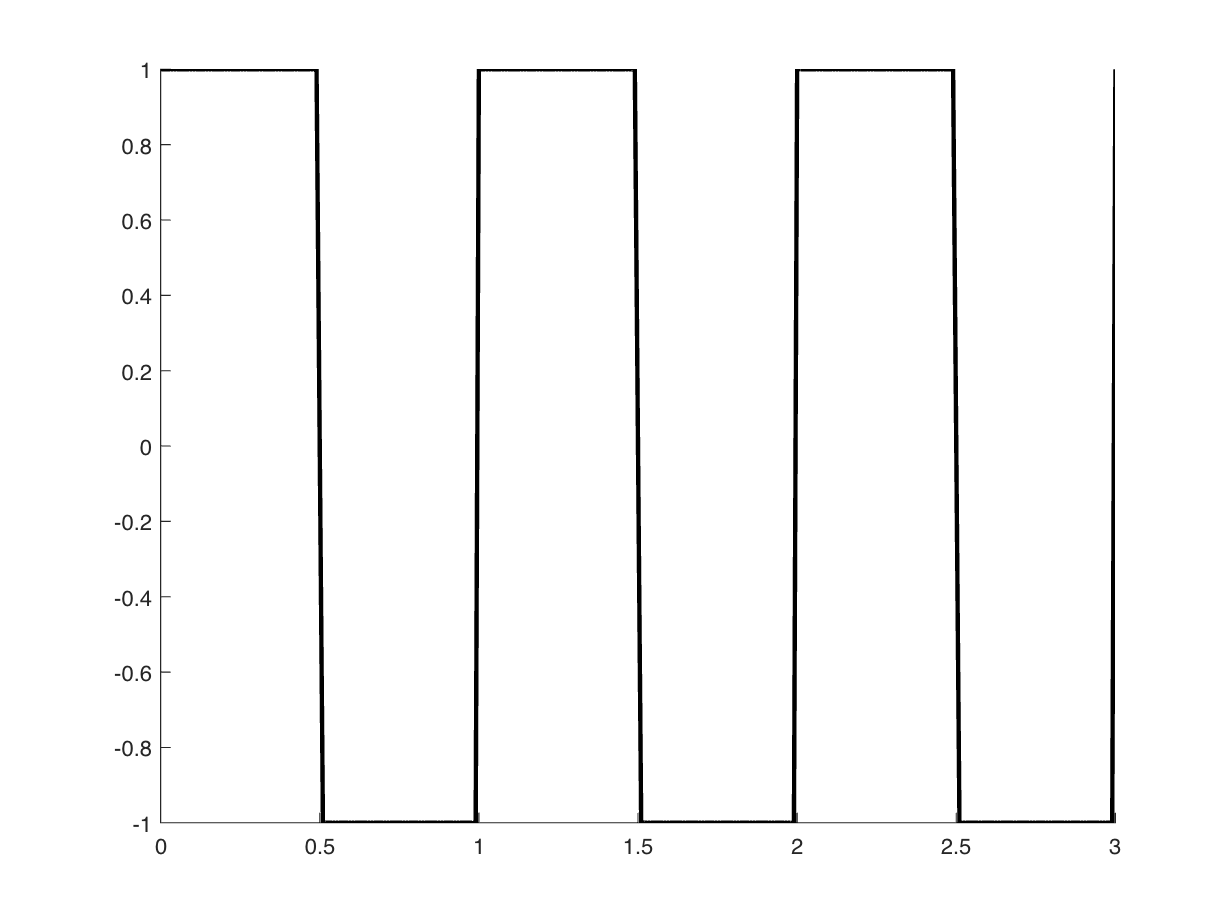

figure; hold on;

f = @(t) sign(0.5-mod(t,1));
ts=(0:0.01:3)';
plot(ts,f(ts),'-k','LineWidth',2); hold off;

The Fourier series representation of this periodic function is given by the infinite series (you may consult/review your MAA901 notes on Fourier series here)


$$f(t) = \frac{4}{\pi}\sum_{k=0}^\infty\frac{1}{2k+1}\sin[2\pi(2k+1)t]$$


We may truncate this series up to a maximum number $k_{\text{max}}$of harmonics and explore how the resulting approximation 


$$f_{\text{trunc}}(t) = \frac{4}{\pi}\sum_{k=0}^{k_{\text{max}}}\frac{1}{2k+1}\sin[2\pi(2k+1)t]$$


converges to the original function. Write a Matlab function (either in a separate file or at the end of this main script, see bototm) that takes $t$ and $k_{\text{max}}$and returns the value of $f_{\text{trunc}}(t)$. Then write a few lines of code below where you use that Matlab function to generate a plot of $f_{\text{trunc}}(t)$ on top of the above plot of $f(t)$ for $k_{\text{max}}=1$.

%add your code here

Repeat for $k_{\text{max}}=2,3,10,100$ to check the convergence.

## B. Fourier series of triangle wave

Repeat the above for the "triangle wave" shown below

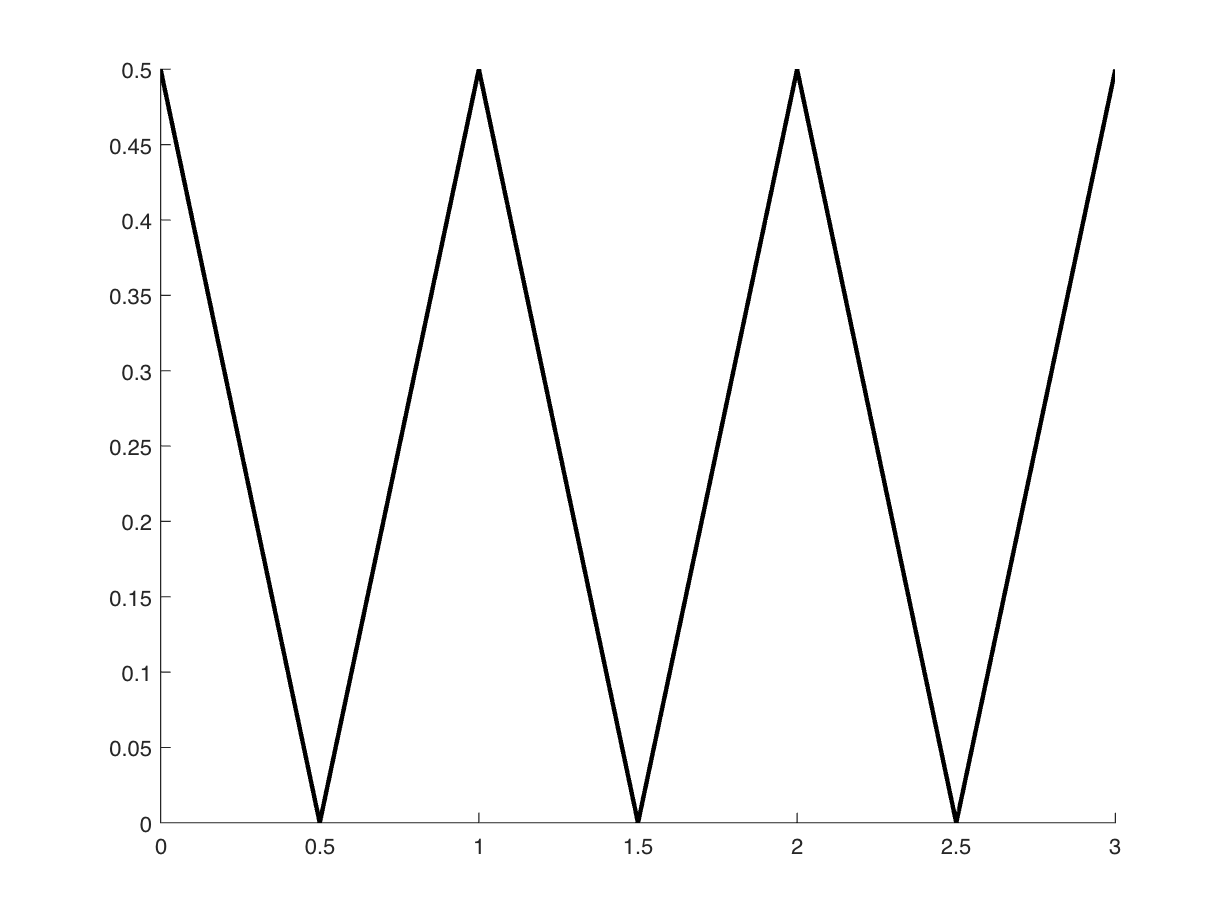

figure; hold on;

g = @(t) abs(0.5-mod(t,1));
ts=(0:0.01:3)';
plot(ts,g(ts),'-k','LineWidth',2); hold off;

whose Fourier series representation is given by 


$$g(t) =\frac{1}{4}+ \frac{2}{\pi^2}\sum_{k=0}^\infty\frac{1}{(2k+1)^2}\cos[2\pi(2k+1)t]$$


function FT1 = FTofSquareWave(x,kmax)
%add your function here
end

function FT2 = FTofTriangleeWave(x,kmax)
%add your function here
end